# Module 1: Temporal median filtering

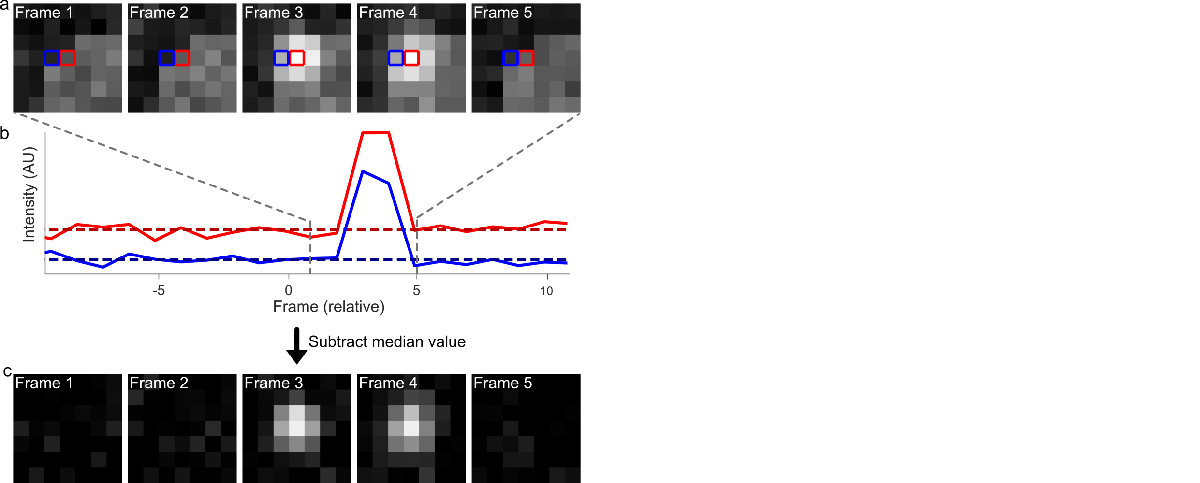

Temporal median filtering is a technique to remove background from the image stack before localization is performed.

Briefly, it can be reasonably assumed that each pixel does not contain an emitting fluorophore for the majority of the time. Therefore, the median value of each pixel over a rolling temporal window is a good approximation for the background value of that pixel. By then subtracting this background, subsequent emitter localization is more robust, and background gradients are decreased.

## Variable initiation

%Load an example movie - TIFF movie loading in MATLAB is somewhat involved.
%We first need to get information about the size of the image stack via
%imfinfo, then read the data frame-by-frame with imread.
im_info = imfinfo('Data\DNAPAINT_substack.tiff'); %Returns info about image
im = imread('Data\DNAPAINT_substack.tiff', 1) ; % read in first frame
%Add each subsequent frame to the image
for ii = 2:size(im_info, 1)
    newframe = imread('Data\DNAPAINT_substack.tiff', ii);
    im = cat(3 , im, newframe);
end

## Visualisation of inhomogeneous background

Let's look at a frame somewhere in the center to showcase that there is quite a bit of background present. We will use the same colourmap after the temporal median filter for a good comparison.

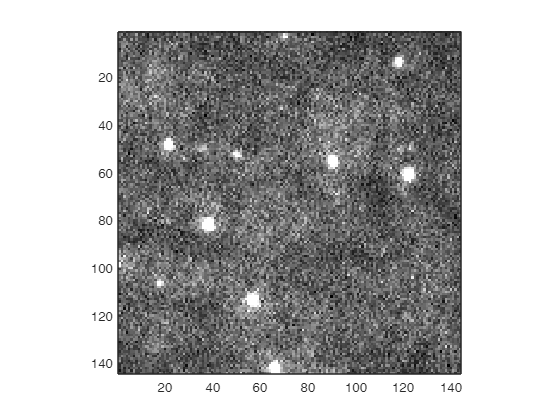

figure();
%First we read the data of the single frame present in DNAPAINT_substack.tif file
singleFrame = im(:,:,55);
%We plot this image with a gray colormap and minimum and maximum colormap values to showcase the individual localizations
imagesc(singleFrame);
colormap('gray')
caxis([2312 6500]);
axis square

## Definition of temporal median calculation

We define the temporal median calculation as a function with variables x,y, and central t (i.e. frame) position. Please note that this is not at all optimized for analysis speed.

Since MATLAB requires functions to be at the end of a document, please look at the function TemporalMedianFilterSingleVoxel on **line 43** (hyperlink).

Now, we can simply call that for all x,y,t positions - this is created as the function TemporalMedianFilterFullMovie** line 76** (hyperlink) -  and use the output to populate a new image. Note that this implementation is slow, so this cell can take up to 5 minutes to process.

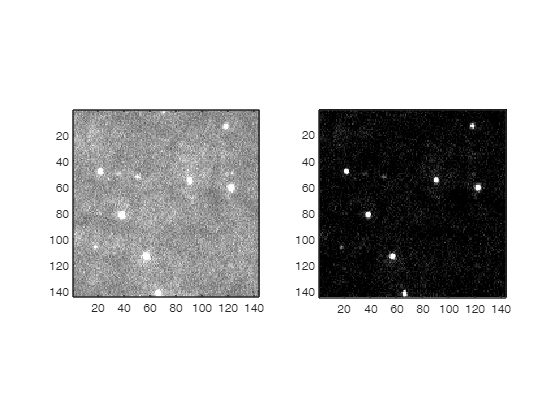

%Create a variable for the temporal length
TemporalLength = 51;

%Run the calculation
MedianFilteredImage = TemporalMedianFilterFullMovie(im,TemporalLength);

%First we read the data of the single frame present in DNAPAINT_substack.tif file
singleFramePreTempFilt = im(:,:,55);
singleFramePostTempFilt = MedianFilteredImage(:,:,55);

%We plot this image with a gray colormap to showcase the individual localizations
%Note that the minimum value of the Temporal Filtered image is much lower, indicating that all background noise is effectively removed
figure()
subplot(1,2,1)
imagesc(singleFramePreTempFilt);
colormap('gray')
caxis([0 6500]);
axis square

subplot(1,2,2)
imagesc(singleFramePostTempFilt);
colormap('gray')
caxis([0 6500]);
axis square

## Function declaration

function medSubtractedValue = TemporalMedianFilterSingleVoxel(ImageStack,x,y,t,TemporalLength)
    %Required parameters: the imageStack, xyt position, and the length of the rolling temporal window
    
    %We have to prevent that an x,y, or t value outside the range is chosen
    if (x >= 0) && (x<=size(ImageStack,1)) && (y >= 0) && (y<=size(ImageStack,2)) && (t >= 0) && (t<=size(ImageStack,3))
        %Now we have to determine the start and end T values over which the temporal median filter has to be performed.
        %If the t position is in the middle of the stack, this is easy, then T = [t-(TemporalLength-1)/2:t+(TemporalLength-1)/2]
        %However, if t is on the edge of the stack, this should be shifted
        startT = t - (TemporalLength-1)/2;
        endT = t + (TemporalLength-1)/2+1;
        if startT < 1
            endT = endT - startT;
            startT = 1;
        end
        if endT > size(ImageStack,3)
            startT = startT - (endT-size(ImageStack,3));
            endT = size(ImageStack,3);
        end
    
        %And now it is possible to calculate the median value of pixel x,y at time t
        %Note that images are t,x,y
        medianValue = median(ImageStack(x,y,startT:endT));
        %And we return the median-subtracted value, ensuring that the minimum value possible is 0
        if ImageStack(x,y,t) >= medianValue
            medSubtractedValue = ImageStack(x,y,t) - medianValue;
        else
            medSubtractedValue = 0;
        end
    end
end



function MedianFilteredMovie = TemporalMedianFilterFullMovie(im,TemporalLength)
  %Create an empty image
  MedianFilteredMovie = zeros(size(im));

  %Populate the empty image
  for xx = 1:size(im,1)
    for yy =1:size(im,2)
      for tt = 1:size(im,3)
        MedianFilteredMovie(xx,yy,tt) = TemporalMedianFilterSingleVoxel(im,xx,yy,tt,TemporalLength);
      end
    end
  end
end